## Bootstrap分析

Bootstrap是现代统计学较为流行的一种统计方法,在小样本时效果很好.通过方差的估计可以构造置信区间等,其运用范围得到进一步延伸

- 具体抽样方法举例：想要知道池塘里面鱼的数量,可以先抽取N条鱼,做上记号,放回池塘.

- 进行重复抽样,抽取M次,每次抽取N条,考察每次抽到的鱼当中有记号的比例,综合M次的比例,在进行统计量的计算.。

- https://blog.csdn.net/Alexander_Frank/article/details/79106383

## Main

- 同时指定多个时间点时，将不同时间点对应的同一个细胞认为是独立的？

- dataOrigi(fi).metric_rand  真值

- dataOrigi(fi).metric_rand  Bootstrap分析结果

clc
clear
close all
cd('E:\temp projs\2025-01-12 WSL 2p分析\test for sf')


**参数设置，需要修改**

% *******************************
para_fea = {"指标1","指标2"};  % sheet of excel
% para_time = {'21d','28d','35d','39d', '42d','45d'};  % 时间点
para_time = {'35d','39d', '42d','45d'};  % 时间点
para_bootstrap_num = 50000;  % 随机次数
% *******************************


加载数据及分析

dataOrigi = [];
dataOrigi(1).type = 'control';
dataOrigi(1).file = 'distribution_control_for_sf_2.xlsx';
dataOrigi(2).type = 'test';
dataOrigi(2).file = 'distribution_test_for_sf_2.xlsx';

figure(1)
tiledlayout(1,2);
for fi = 1 : 2
    TR1_mat0 = [];
    for fea_i = 1:2
        TR1 = readcell(dataOrigi(fi).file,Sheet=para_fea{fea_i});
        TR1_timestr = TR1(:,1);
        TR1_mat0 = cat(3,TR1_mat0,cell2mat(TR1(:,2:end)));
    end
    % 时间点匹配
    flag1 = contains(TR1_timestr,para_time);
    if sum(flag1) ~= length(para_time)
        errordlg('时间点参数设置错误（字符串不匹配）！')
        return
    end
    TR1_mat = TR1_mat0(flag1,:,:);

    % 计算真实测量值
    mat1 = min(TR1_mat,[],3);
    mat2 = min(mat1,[],1);
    metric_true = sum(mat2>0)/length(mat2);
    dataOrigi(fi).metric_true = metric_true;

    % bootstrap
    metric_rand = zeros(para_bootstrap_num,1);
    for ri = 1:para_bootstrap_num
        TR1_mat1 = TR1_mat0;
        sampSize = size(TR1_mat0);
        for fea_i = 1:2
            mat_tar = TR1_mat1(:,:,fea_i);
            mat_tar = reshape(mat_tar,[],1);
            mat_tar = mat_tar(randperm(length(mat_tar)));
            mat_tar = reshape(mat_tar,sampSize(1),sampSize(2));
            TR1_mat1(:,:,fea_i) = mat_tar;
        end
        TR1_mat = TR1_mat1(flag1,:,:);
        mat1 = min(TR1_mat,[],3);
        mat2 = min(mat1,[],1);
        metric1 = sum(mat2>0)/length(mat2);
        metric_rand(ri) = metric1;
    end
    dataOrigi(fi).metric_rand = metric_rand;   
    % 95% 置信区间
    conf = 0.95;
    alpha = 1 - conf;
    [h,p,ci2] = ttest(metric_rand,mean(metric_rand),'Alpha',alpha);
    % update info
    disp(dataOrigi(fi).file)
    fprintf('Metric true %.4f  \n', dataOrigi(fi).metric_true)
    fprintf('Bootstrap 95%% CI [%.4f %.4f]   \n \n', ci2(1),ci2(2))
    % visualization
    nexttile; hold on
    hx = 0:0.02:1;
    hy = hist(metric_rand,hx);
    hy(hy==0) = nan;
    hy = fillmissing(hy,'movmean',3);
    hy(isnan(hy)) = 0;
    hy = hy/sum(hy);
    plot(hx,hy)
    plot([1 1]*metric_true,[0 max(hy)],'r--')
    legend('bootstrap','true')
    xlabel('metric'); ylabel('probability')
    title(dataOrigi(fi).type)
end

distribution_control_for_sf_2.xlsx


Metric true 0.0571  


Bootstrap 95% CI [0.0009 0.0010]   
 


distribution_test_for_sf_2.xlsx


Metric true 0.1250  


Bootstrap 95% CI [0.0012 0.0013]   
 


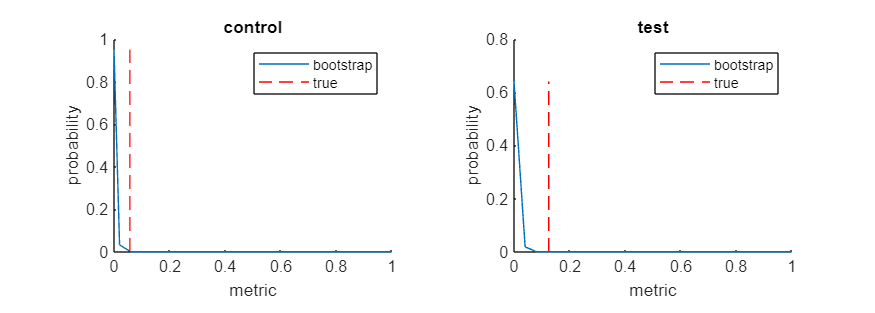

set(gcf,'Position',[100 100 700 250])